wpl = 0.2*pi; wsl = 0.1*pi; wpu = 0.4*pi; wsu=0.6*pi;
rs = 20;
rp = 2;
w = [wpl, wsl, wpu, wsu];
W = tan(w/2);
Wpl = W(1); Wsl = W(2); Wpu = W(3); Wsu= W(4);
Wpl*Wpu;
Wsl*Wsu;
% Wpl =W(2) *W(4)/W(3);
Wsl = W(1)*W(3)/W(4);
W0 = (Wpl+Wpu)/2; %中心频率
Bw = Wpu - Wpl;

v

fpl = 200; fpu = 400; fsl = 100; fsu = 600;
ws = [2*fsl/Fs, 2*fsu/Fs]; wp = [2*fpl/Fs, 2*fpu/Fs];
rp = 2;
rs = 20;
[N, wc] = buttord(wp, ws, rp, rs, 's')

N =      4


wc =    0.180487687919762   0.443243530470428



[B, A] = butter(N, wc, 's')   % 获得系统函数

B =                    0                   0                   0                   0   0.004766608976666                   0                   0                   0                   0


A =    1.000000000000000   0.686614105363177   0.555719464841838   0.212191657607073   0.080881723351361   0.016975332608566   0.003556604574988   0.000351546421946   0.000040960000000



wpl = 0.2*pi; wsl = 0.1*pi; wpu = 0.4*pi; wsu=0.6*pi;

a


[N, wc] = buttord(wp, ws, rp, rs, 's')

N =      4


wc =    0.180487687919762   0.443243530470428



lambda_s = (W0^2 + Wsl^2)/(Wsl*Bw);
ksp =  sqrt( ( 10^(rs/10) -1) / ( 10^(rp/10) -1  ) );
N = log10(ksp)/log10(lambda_s)

N =    1.721332669117835



wp = 2*pi*[200, 400] ; ws = 2*pi*[100 , 600]

ws = 	1.0e+03 *

   0.628318530717959   3.769911184307752



[N, wc] = buttord(wp, ws, rp, rs, 's')

N =      4


wc = 	1.0e+03 *

   1.134037588864262   2.784981238154198


[B, A] = butter(N, wc, 's')   % 获得系统函数

B = 	1.0e+12 *

                   0                   0                   0                   0   7.428976763705490                   0                   0                   0                   0


A = 	1.0e+25 *

   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000005   0.000000000012606   0.000000016623315   0.000021883399707   0.013590697951392   9.949445898707198


a

fpl = 200; fpu = 400; fsl = 100; fsu = 600;
Fs = 2000;
wpl = 2*fpl/Fs; wpu = 2*fpu/Fs;  wsl = 2*fsl/Fs; wsu=2*fsu/Fs;

% wpl = 0.2*pi; wsl = 0.1*pi; wpu = 0.4*pi; wsu=0.6*pi;
rp = 2;
rs = 20;

[N, wc] = buttord([wpl , wpu], [wsl, wsu], rp, rs);
[B, A] = butter(N, wc)   % 获得系统函数

B =    0.038619666292792                   0  -0.115858998878376                   0   0.115858998878376                   0  -0.038619666292792


A =    1.000000000000000  -2.678833058409780   3.810701616828999  -3.439215526936194   2.141169006824264  -0.819496518453103   0.170643237870783


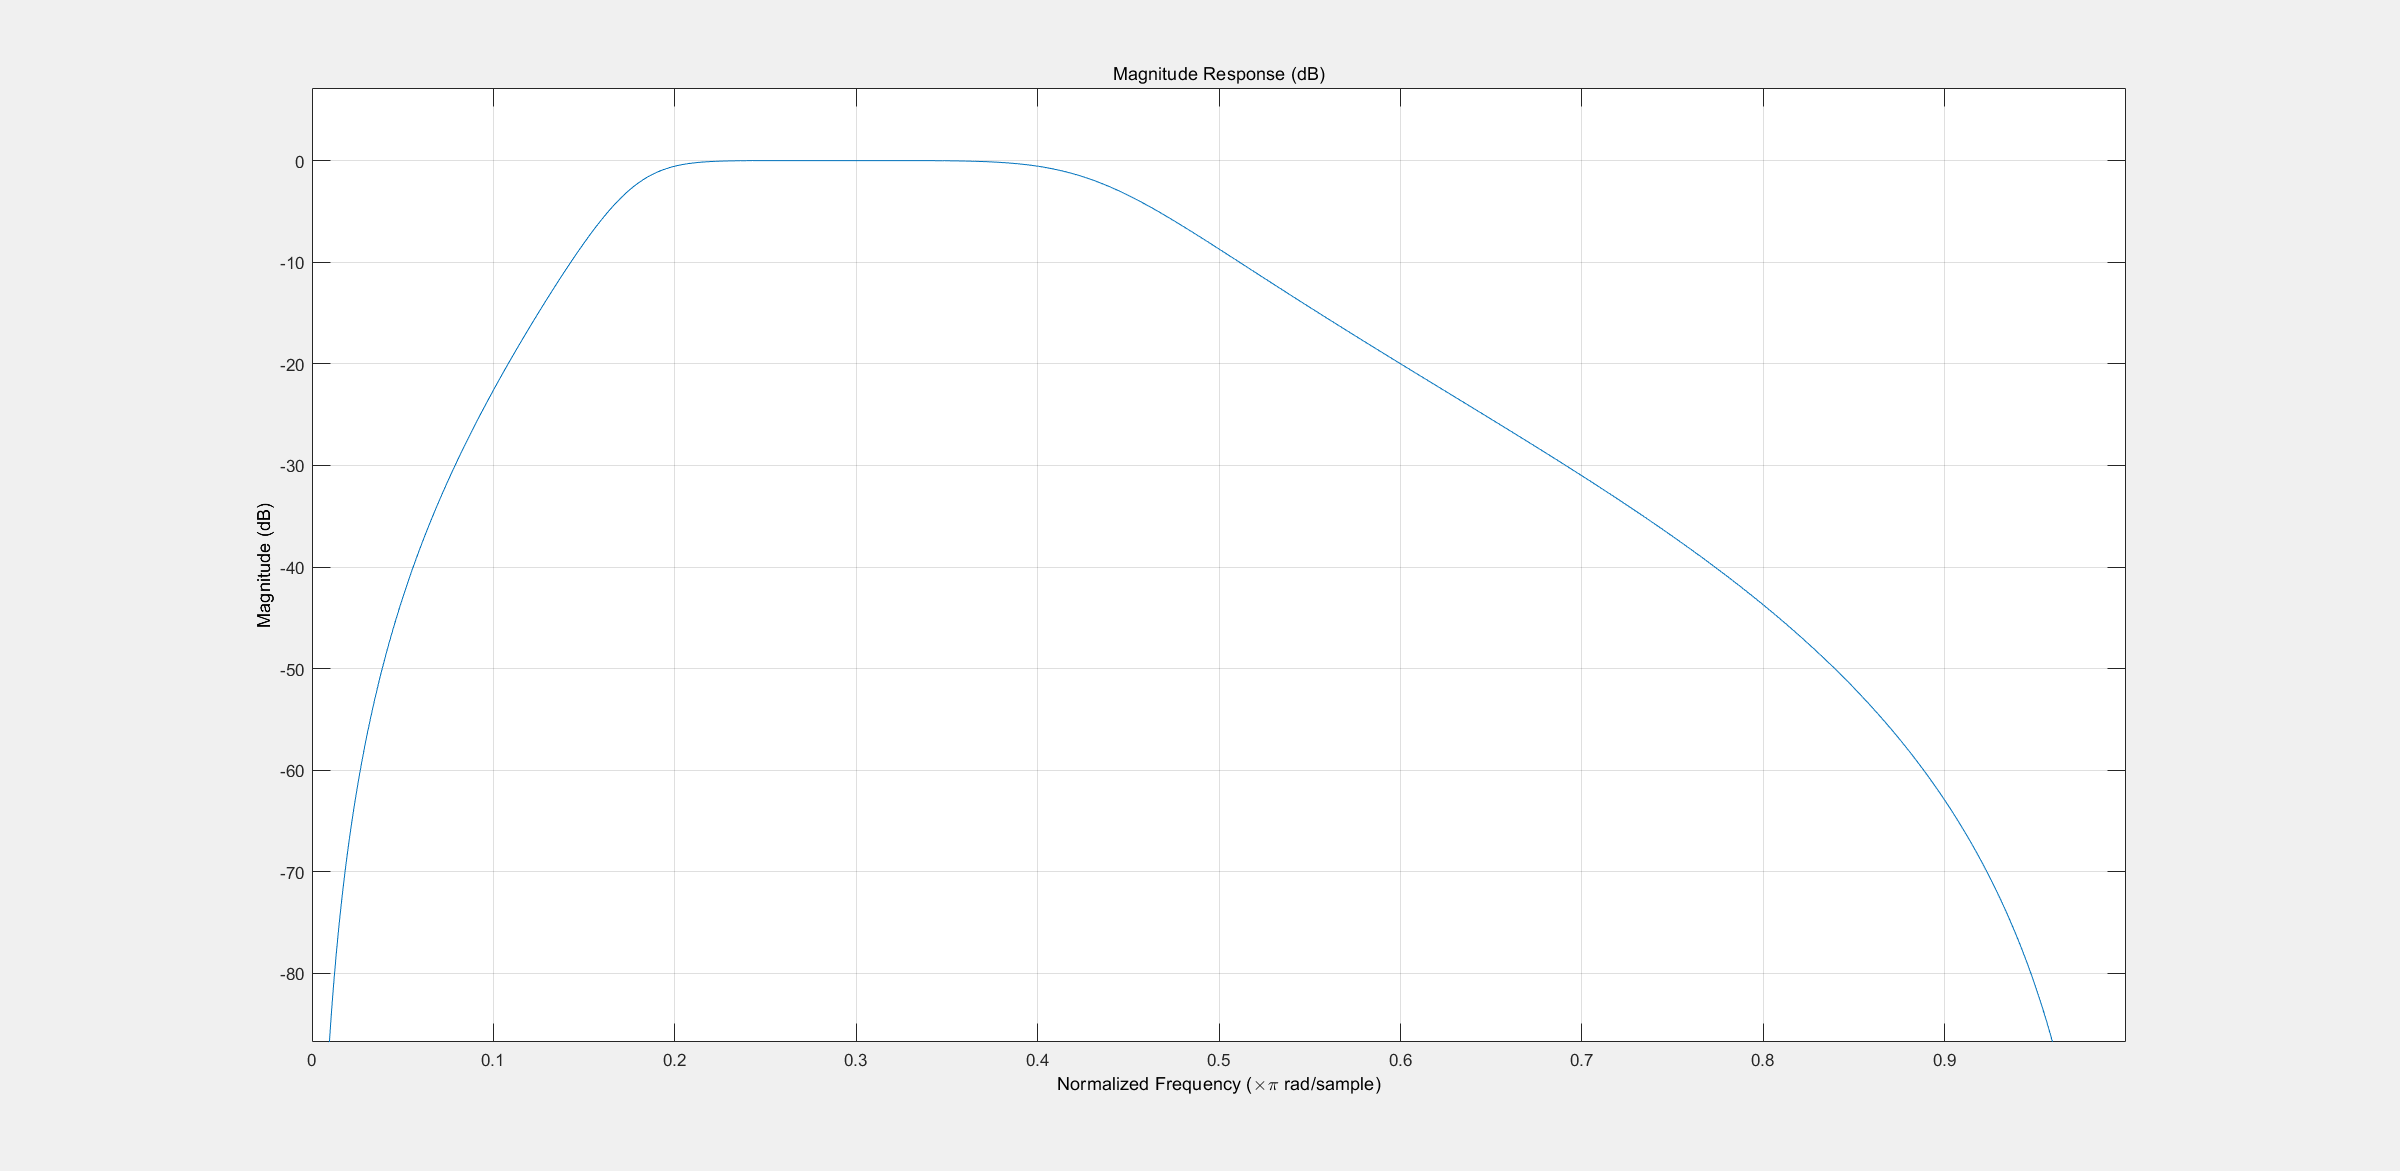



fvtool(B,A); % 显示滤波器图像

khj

wp= 0.25; ws = 0.5

ws =    0.500000000000000


rp = 3;   rs = 40;
[N, wc] = buttord(wp, ws, rp, rs);
[B, A] = butter(N, wc, 'low')

B =    0.001737585527782   0.010425513166691   0.026063782916728   0.034751710555637   0.026063782916728   0.010425513166691   0.001737585527782


A =    1.000000000000000  -2.659046466914585   3.446507115469457  -2.563396532484719   1.138899255022834  -0.281949931978518   0.030192034663570


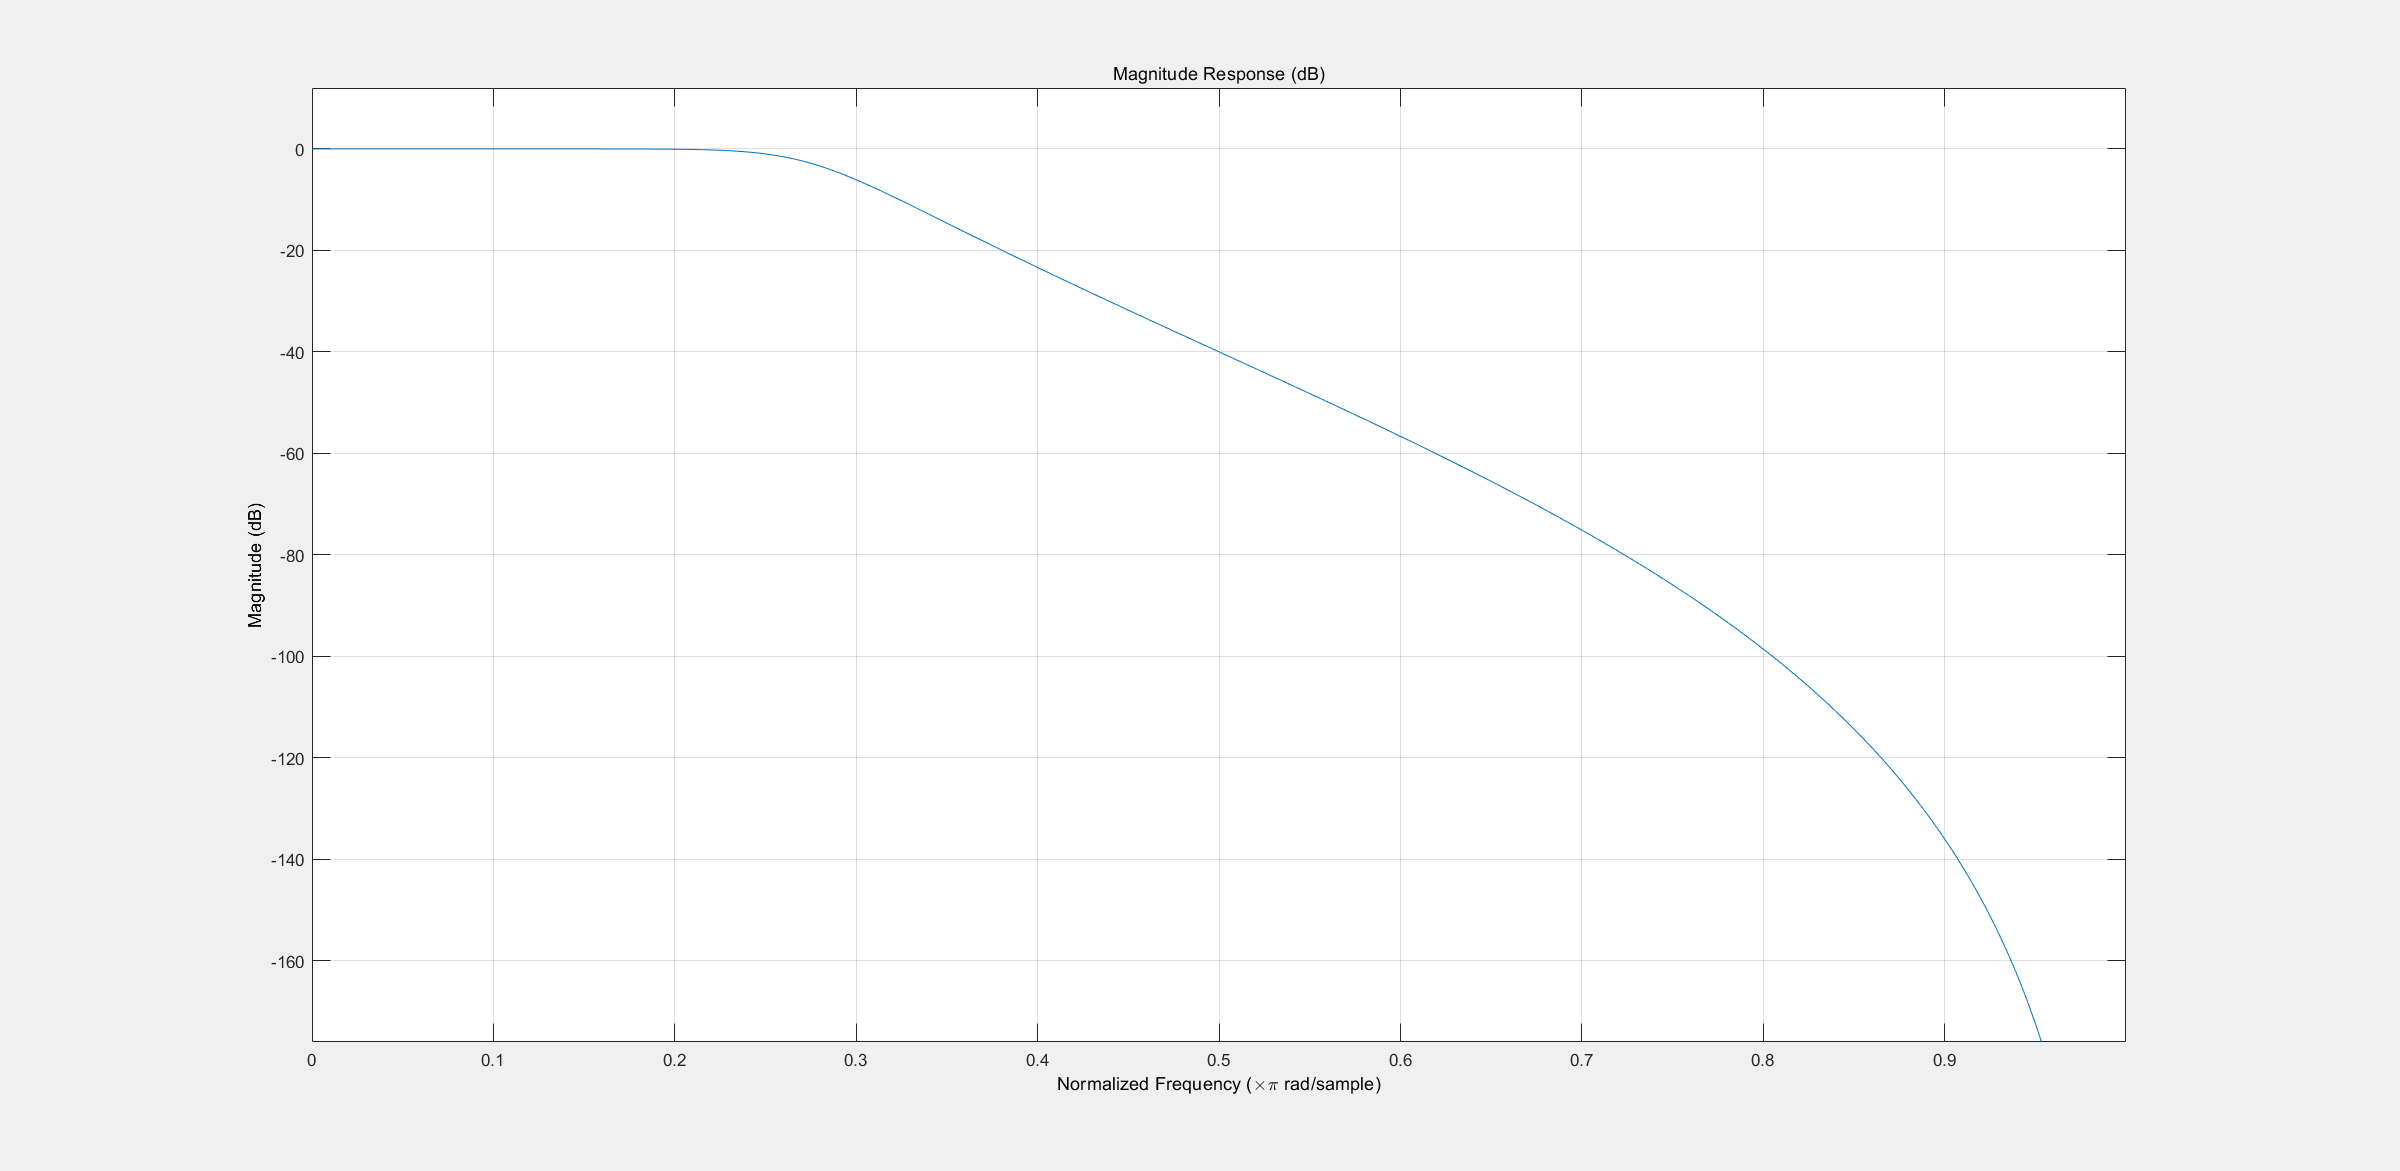

fvtool(B, A )

redt

wph = 0.5; ws = 0.3

ws =    0.300000000000000



[N, wc] = buttord(wph, ws, 3, 30)

N =      6


wc =    0.468629715046590


[B, A] = butter(N, wc, 'high')

B =    0.039421789216380  -0.236530735298277   0.591326838245693  -0.788435784327590   0.591326838245693  -0.236530735298277   0.039421789216380


A =    1.000000000000000  -0.372327092047943   0.829439017478270  -0.179288293752465   0.127721749833089  -0.012188912609813   0.002029444126709


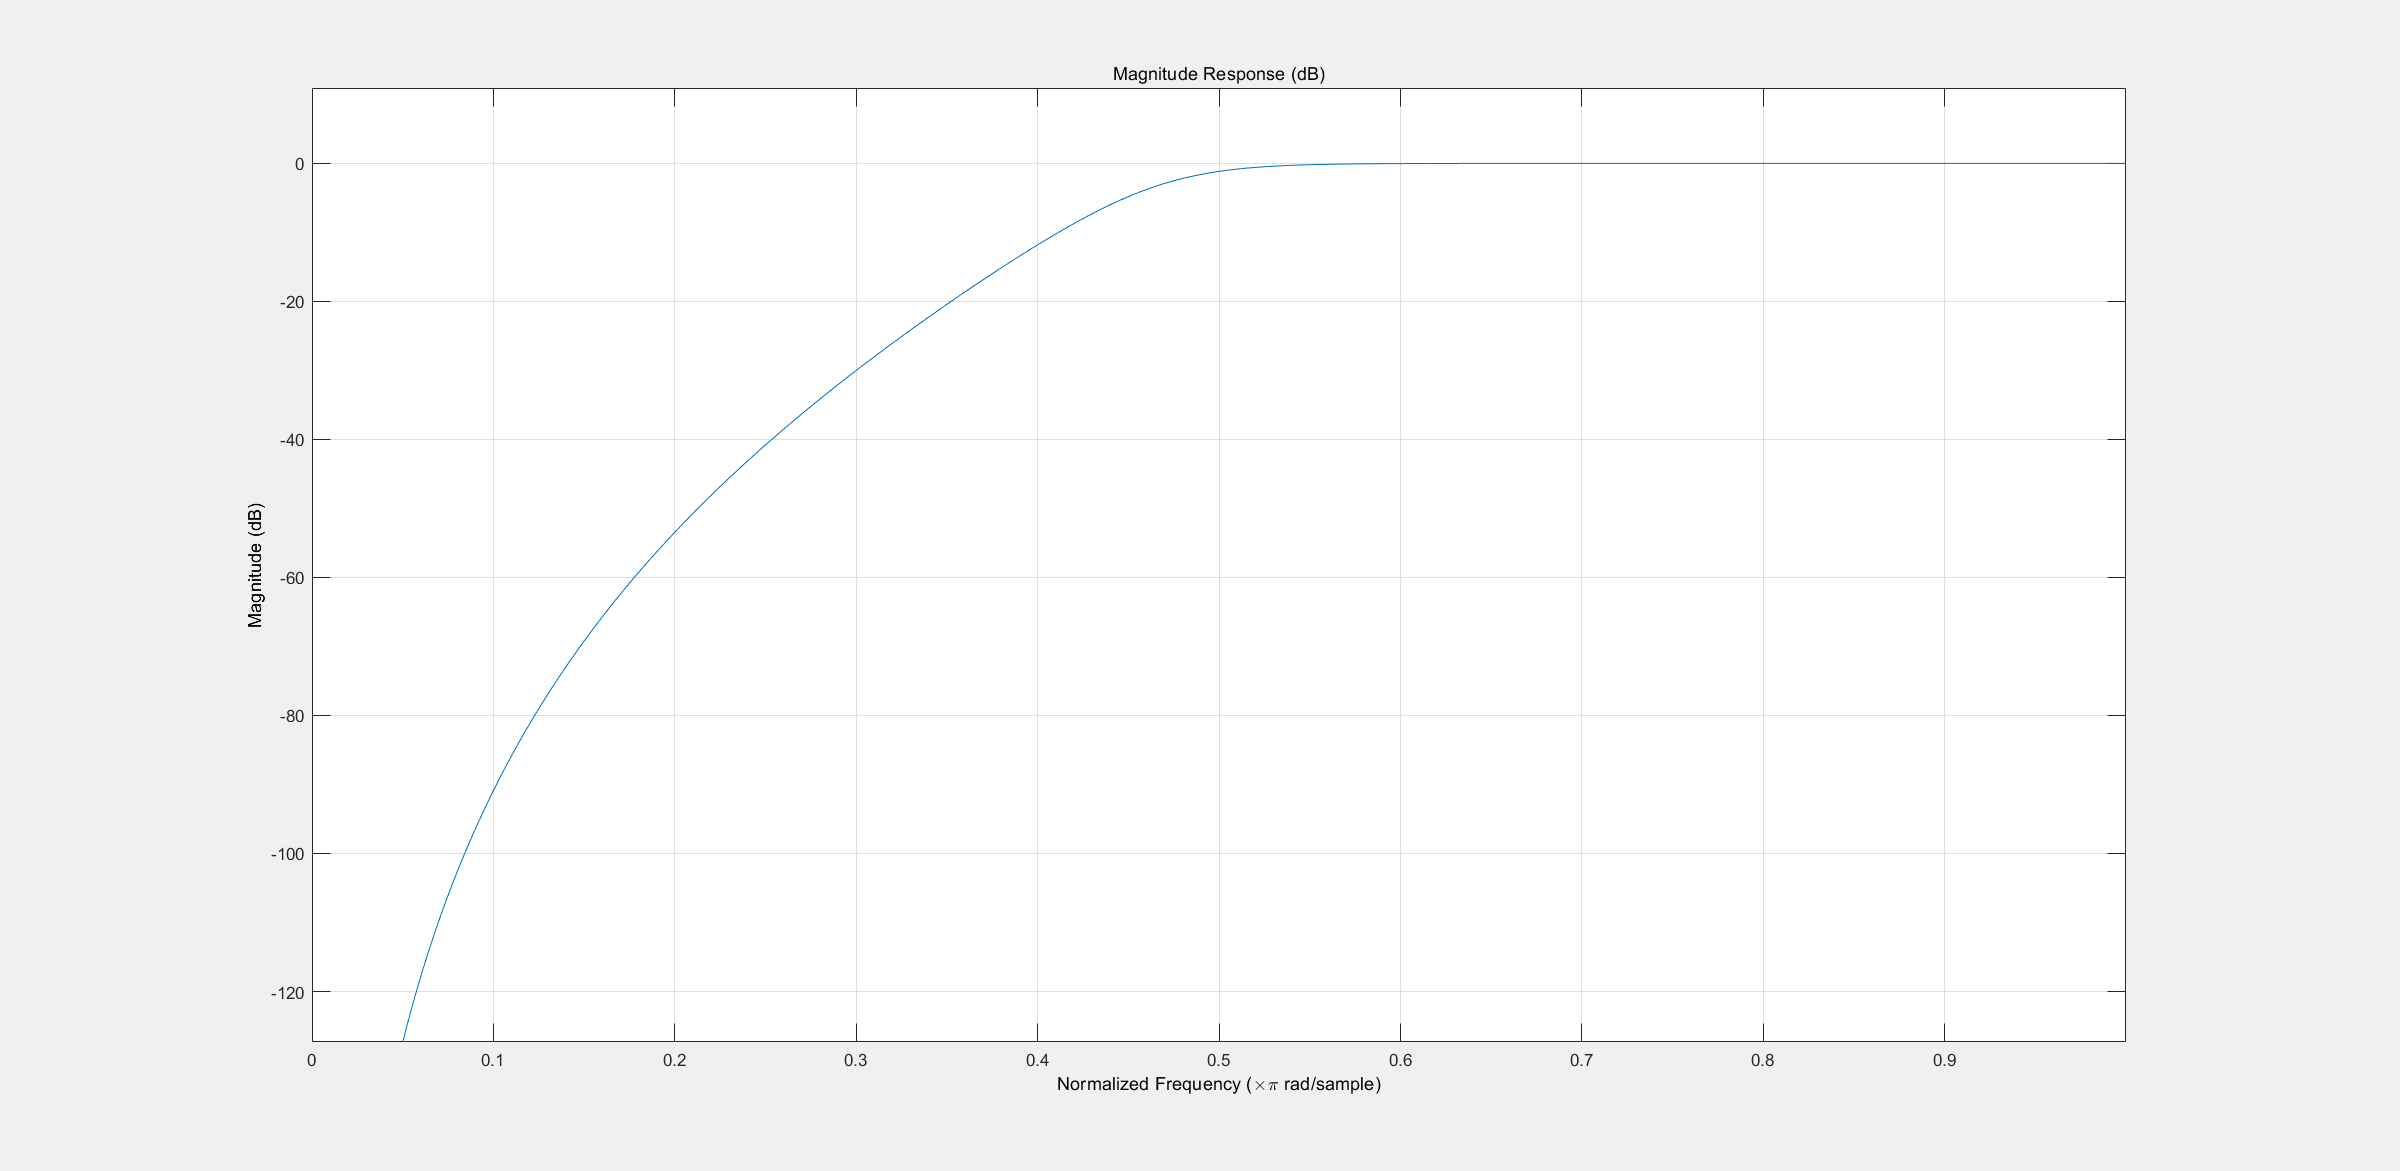

fvtool(B, A )